## 中国银行收盘价 ARIMA 建模（MATLAB Live Script 版）

说明：本脚本等价于 Notebook 的主要步骤，使用 MATLAB Econometrics 工具箱完成 - 数据读取与时间筛选 - 训练/测试划分 - 平稳性检验（ADF） - ACF/PACF 分析 - (p,q) 网格搜索（以 AIC/BIC 选择） - 拟合 ARIMA 并预测测试集 - 可视化

## 1. 导入数据

假设数据文件 ChinaBank.csv 包含列：Date, Close（Date 为可解析日期字符串）

T = readtable('ChinaBank.csv', 'TextType', 'string');
T.Date = datetime(T.Date, 'InputFormat','yyyy-MM-dd', 'Format','yyyy-MM-dd');
TT = table2timetable(T, 'RowTimes','Date');

## 2. 提取 Close 列，并筛选 2014-01 ~ 2014-06

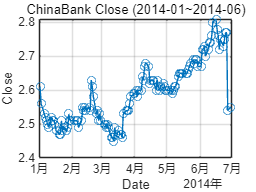

startDate = datetime(2014,1,1);
endDate   = datetime(2014,6,30);

sub = TT(timerange(startDate, endDate, 'closed'), 'Close');
figure('Name','2014-01~2014-06 Close');
plot(sub.Date, sub.Close, '-o'); grid on;
xlabel('Date'); ylabel('Close'); title('ChinaBank Close (2014-01~2014-06)');

## 3. 划分训练/测试集

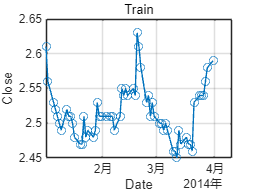

train = TT(timerange(datetime(2014,1,1), datetime(2014,3,31), 'closed'), 'Close');
test  = TT(timerange(datetime(2014,4,1), datetime(2014,6,30), 'closed'), 'Close');

figure('Name','Train series');
plot(train.Date, train.Close, '-o'); grid on;
xlabel('Date'); ylabel('Close'); title('Train');

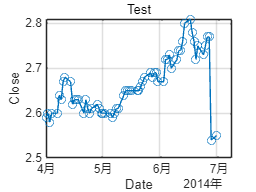


figure('Name','Test series');
plot(test.Date, test.Close, '-o'); grid on;
xlabel('Date'); ylabel('Close'); title('Test');

## 4. 平稳性与差分

ADF 单位根检验（Econometrics Toolbox）

if exist('adftest','file') == 2
    [h_adf,p_adf,stat_adf,cValue] = adftest(train.Close);
    fprintf('ADF: h=%d, p=%.4g, stat=%.4f\n', h_adf, p_adf, stat_adf);
else
    warning('未检测到 adftest（Econometrics Toolbox），跳过 ADF 检验。');
end

ADF: h=0, p=0.5946, stat=-0.1451


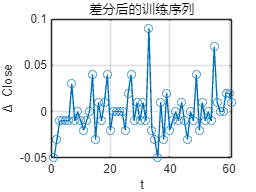


% 一阶差分
d = 0;
y = train.Close;
if exist('adftest','file') == 2
    if ~adftest(y)
        y = diff(y);
        d = 1;
    end
else
    % 无法做 ADF，则默认 d=1（可按需修改）
    y = diff(y);
    d = 1;
end

figure('Name','Diff(train)');
plot(y, '-o'); grid on; xlabel('t'); ylabel('\Delta Close'); title('差分后的训练序列');

## 5. ACF / PACF

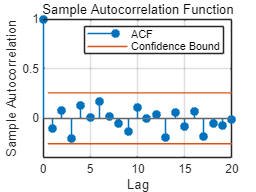

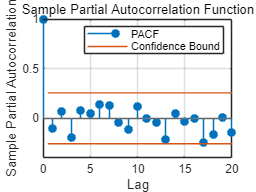

if exist('autocorr','file') == 2 && exist('parcorr','file') == 2
    figure('Name','ACF');
    autocorr(y);
    figure('Name','PACF');
    parcorr(y);
else
    warning('未检测到 autocorr/parcorr 函数，跳过 ACF/PACF 绘图。');
end

## 6. (p, q) 网格搜索（max 8），以 AIC/BIC 最小为准

需要 Econometrics Toolbox: arima / estimate / aicbic

maxPQ = 8;
bestAIC = inf; bestBIC = inf;
bestAIC_pq = [NaN,NaN]; bestBIC_pq = [NaN,NaN];

if exist('arima','file') == 2 && exist('estimate','file') == 2
    for p = 0:maxPQ
        for q = 0:maxPQ
            try
                Mdl = arima(p,d,q);
                % 对差分后的序列估计需要指定 'Y0' 或者直接对原序列估计。
                % 我们在这里对原始 train.Close 估计，模型自带 d。
                [EstMdl,~,logL] = estimate(Mdl, train.Close, 'Display','off');
                % 参数个数近似：p+q + 常数 + 方差（粗略，足够用于比较）
                numParams = p + q + 2;
                [aic_val,bic_val] = aicbic(logL, numParams, numel(train.Close));
                % AIC
                if aic_val < bestAIC
                    bestAIC    = aic_val;
                    bestAIC_pq = [p,q];
                end
                % BIC
                if bic_val < bestBIC
                    bestBIC    = bic_val;
                    bestBIC_pq = [p,q];
                end
            catch ME %#ok<NASGU>
                % 部分 (p,q) 组合可能无法收敛或不适用，直接跳过
                continue
            end
        end
    end
    fprintf('AIC 最优 (p,q) = (%d,%d), AIC=%.4f\n', bestAIC_pq(1), bestAIC_pq(2), bestAIC);
    fprintf('BIC 最优 (p,q) = (%d,%d), BIC=%.4f\n', bestBIC_pq(1), bestBIC_pq(2), bestBIC);
else
    warning('未检测到 Econometrics Toolbox（arima/estimate），跳过网格搜索。');
end

## 7. 拟合最终 ARIMA 并预测测试集

选用 BIC 最优（也可改 AIC）

if exist('arima','file') == 2 && exist('estimate','file') == 2 && exist('forecast','file') == 2
    if all(~isnan(bestBIC_pq))
        p = bestBIC_pq(1); q = bestBIC_pq(2);
    else
        % 兜底：若未能搜索出，默认用 ARIMA(1,d,1)
        p = 1; q = 1;
    end
    FinalMdl = arima(p,d,q);
    FinalEst = estimate(FinalMdl, train.Close, 'Display','off');

    % 预测长度 = 测试集长度
    h = height(test);
    [yf, yfMSE] = forecast(FinalEst, h, 'Y0', train.Close);

    % 可视化：训练 + 测试 + 预测
    figure('Name','预测结果');
    hold on; grid on;
    plot(train.Time, train.Close, '-b', 'DisplayName','Train');
    plot(test.Time,  test.Close,  '-k', 'DisplayName','Test');
    plot(test.Time,  yf,          '-r', 'DisplayName','Forecast');
    % 95% 置信区间
    ub = yf + 1.96*sqrt(yfMSE); lb = yf - 1.96*sqrt(yfMSE);
    plot(test.Time, ub, '--r', 'HandleVisibility','off');
    plot(test.Time, lb, '--r', 'HandleVisibility','off');
    legend('Location','best');
    title(sprintf('ARIMA(%d,%d,%d) 预测', p,d,q));
    xlabel('Date'); ylabel('Close');
else
    warning('缺少 Econometrics Toolbox 的 arima/estimate/forecast，无法拟合预测。');
end